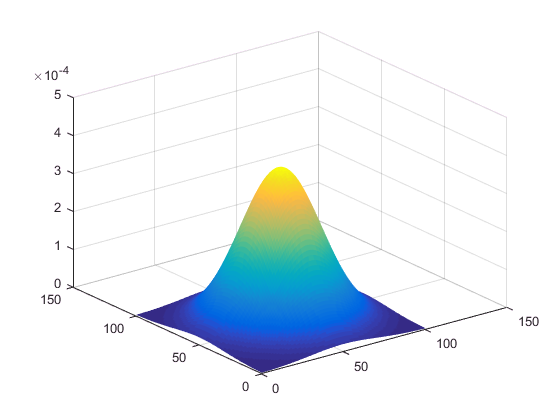

h20=fspecial('gaussian',[101 101],20);
surf(h20,'edgecolor','none');

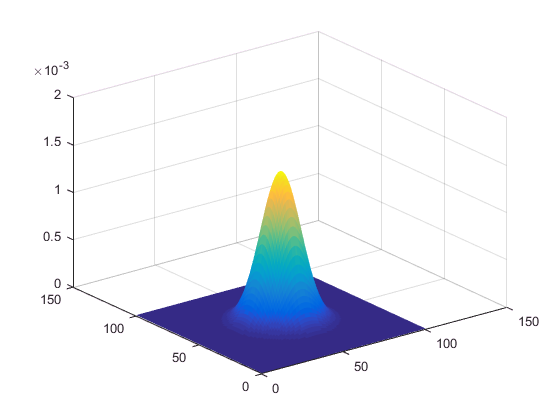

h10=fspecial('gaussian',[101 101],10);
surf(h10,'edgecolor','none');

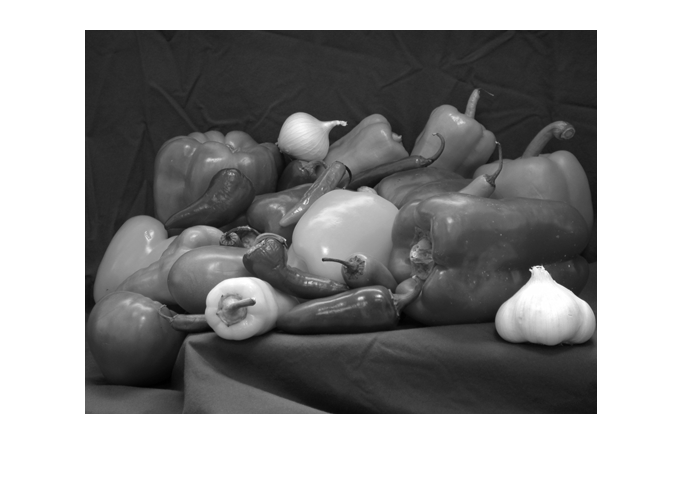


image=rgb2gray(imread('peppers.png'));
imshow(image,[])

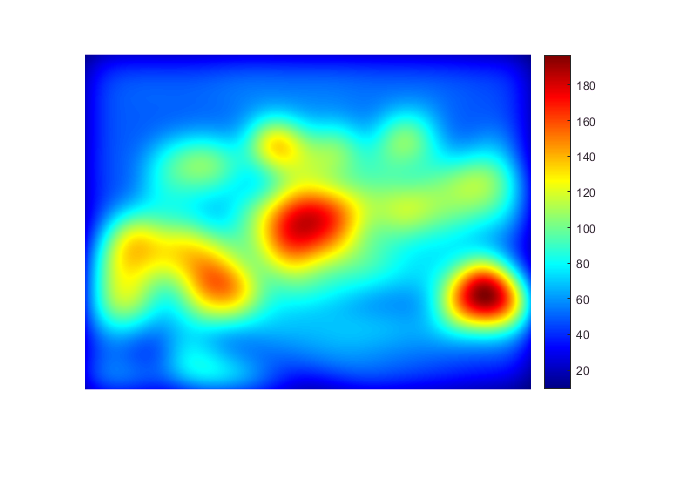

out20=filter2(h20,image);
imshow(out20,[])
colormap jet
colorbar

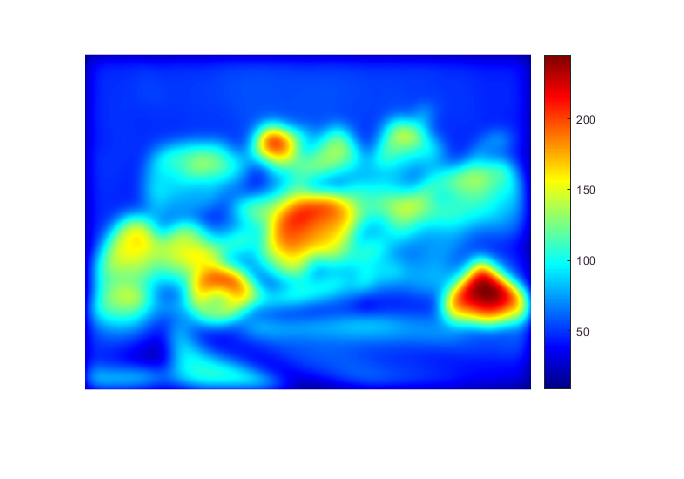

out10=filter2(h10,image);
imshow(out10,[])
colormap jet
colorbar

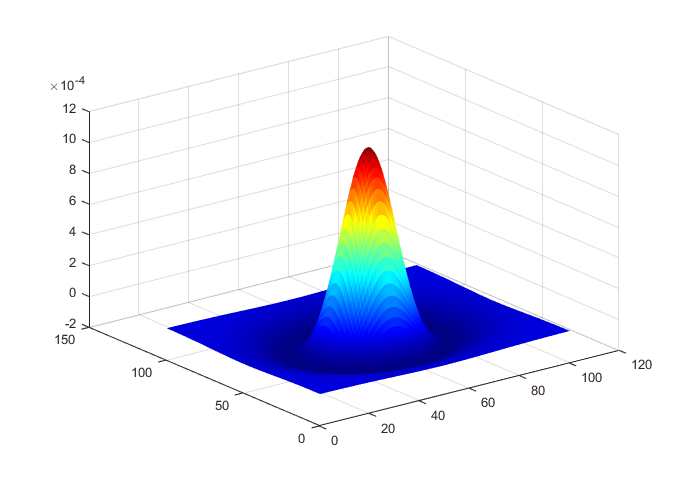

difference=h10-h20;
surf(difference,'edgecolor','none');

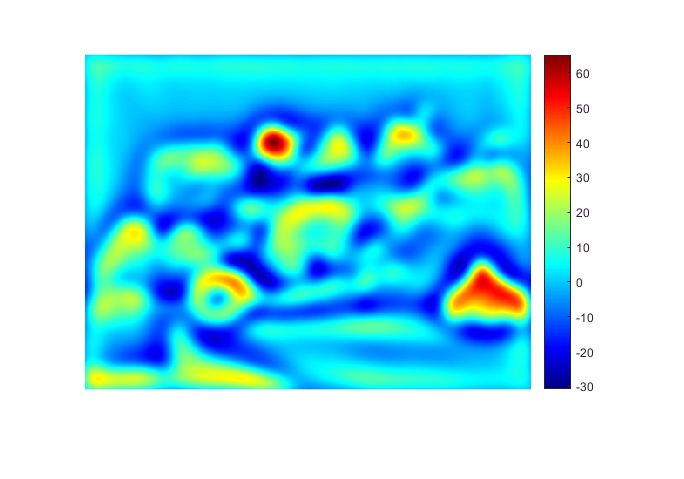

outDifference=filter2(difference,image);
imshow(outDifference,[])
colormap jet
colorbar